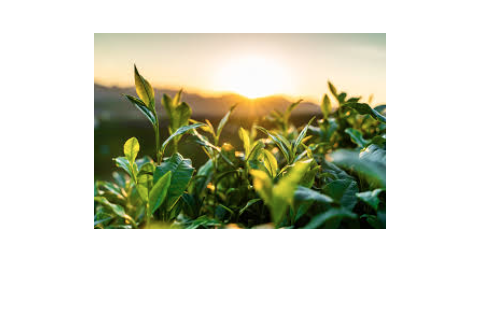

imgRGB = imread('imagem.png');
resized = imresize(imgRGB, [256 256]);
imshow(imgRGB)

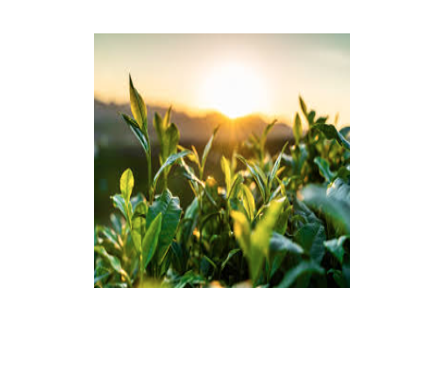

imshow(resized)

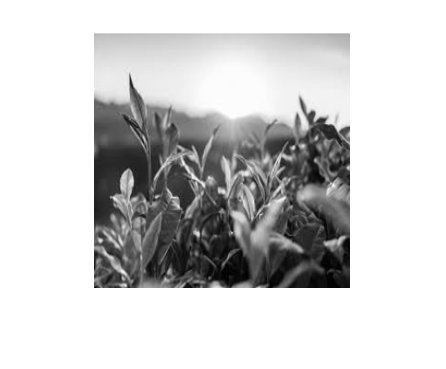

grayScale = rgb2gray(resized);
imshow(grayScale)

imgBits = reshape((dec2bin(grayScale, 8) - '0').', 1, []);
orig_class = class(grayScale);
orig_size = size(grayScale);


% PARAMETRIZAÇÃO
M = 4;
k = log2(M);
numSC = 64; % Número de subcarries
cpLen = 16; % Cyclic Prefix
snr = 4 % Signal to Noise Ratio;

snr = 4


constraint_length = 3;  % Constraint length (K)
code_rate = 1/2;        % Code rate (R)
generator_polynomials = [7, 5];  % Generator polynomials in octal form




sinalModuladoNaoCodificado = qammod(imgBits', M, 'InputType', 'bit');
numSymbolsNaoCodificado = length(sinalModuladoNaoCodificado);
numOFDMSymbolsNaoCodificado = ceil(numSymbolsNaoCodificado / 53);
sinalModuladoNaoCodificado = [sinalModuladoNaoCodificado; zeros(numOFDMSymbolsNaoCodificado * 53 - length(sinalModuladoNaoCodificado), 1)];
sinalModuladoMatrizNaoCodificado = reshape(sinalModuladoNaoCodificado, 53, []);
ofdmModNaoCodificado = comm.OFDMModulator('FFTLength',numSC,'CyclicPrefixLength',cpLen, 'NumSymbols', numOFDMSymbolsNaoCodificado);
ofdmDemodNaoCodificado = comm.OFDMDemodulator('FFTLength',numSC,'CyclicPrefixLength',cpLen, 'NumSymbols', numOFDMSymbolsNaoCodificado);
txSigNaoCodificado = ofdmModNaoCodificado(sinalModuladoMatrizNaoCodificado);
rxSigNaoCodificado = awgn(txSigNaoCodificado, snr, 'measured');
ofdmDemoduladoNaoCodificado = ofdmDemodNaoCodificado(rxSigNaoCodificado);
sinalDemoduladoNaoCodificado = qamdemod(ofdmDemoduladoNaoCodificado, M, 'OutputType', 'bit');
sinalDemoduladoSerialNaoCodificado = reshape(sinalDemoduladoNaoCodificado, 1, []);
imgOutputNaoCodificado = sinalDemoduladoSerialNaoCodificado(1, 1:length(imgBits));

% Create a trellis structure
trellis = poly2trellis(constraint_length, generator_polynomials)

trellis = struct with fields:
     numInputSymbols: 2
    numOutputSymbols: 4
           numStates: 4
          nextStates: [4×2 double]
             outputs: [4×2 double]


sinalCodificado = convenc(imgBits, trellis);
sinalModuladoCodificado = qammod(sinalCodificado', M, 'InputType', 'bit');
% qpskMod = comm.QPSKModulator('BitInput',true);
% qpskDemod = comm.QPSKDemodulator('BitOutput',true);
numSymbolsCodificado = length(sinalModuladoCodificado);
numOFDMSymbolsCodificado = ceil(numSymbolsCodificado / 53);
sinalModuladoCodificado = [sinalModuladoCodificado; zeros(numOFDMSymbolsCodificado * 53 - length(sinalModuladoCodificado), 1)];
sinalModuladoMatrizCodificado = reshape(sinalModuladoCodificado, 53, []);
ofdmModCodificado = comm.OFDMModulator('FFTLength',numSC,'CyclicPrefixLength',cpLen, 'NumSymbols', numOFDMSymbolsCodificado);
ofdmDemodCodificado = comm.OFDMDemodulator('FFTLength',numSC,'CyclicPrefixLength',cpLen, 'NumSymbols', numOFDMSymbolsCodificado);
% ofdmDims = info(ofdmMod);
% numDC = ofdmDims.DataInputSize(1)
% frameSize = [k*numDC 1];
txSigCodificado = ofdmModCodificado(sinalModuladoMatrizCodificado);
rxSigCodificado = awgn(txSigCodificado, snr, 'measured');
ofdmDemoduladoCodificado = ofdmDemodCodificado(rxSigCodificado);
sinalDemoduladoCodificado = qamdemod(ofdmDemoduladoCodificado, M, 'OutputType', 'bit');
sinalDemoduladoSerialCodificado = reshape(sinalDemoduladoCodificado, 1, []);

tbdepth = 1 %N sei como decidir esse número

tbdepth = 1

sinalDecodificado = vitdec(sinalDemoduladoSerialCodificado,trellis,tbdepth,'trunc','hard')

sinalDecodificado =      1     1     1     1     1     1     1     1     1     1     0     1     0     0     0     1     1     0     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     1     1


imgOutputCodificado = sinalDecodificado(1, 1:length(imgBits))

imgOutputCodificado =      1     1     1     1     1     1     1     1     1     1     0     1     0     0     0     1     1     0     1     1     1     0     0     0     1     0     1     1     1     1     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     1     1


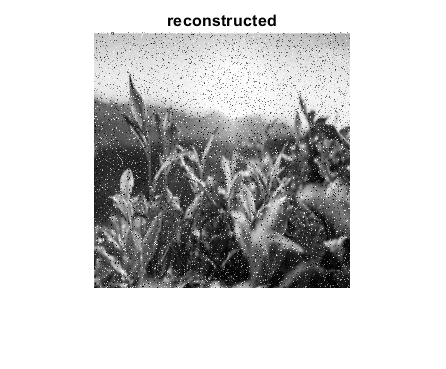


reconstructed = reshape(typecast(uint8(bin2dec(char(reshape(imgOutputNaoCodificado, 8, [])+'0').')), orig_class), orig_size);
figure()
imshow(reconstructed); title('reconstructed')

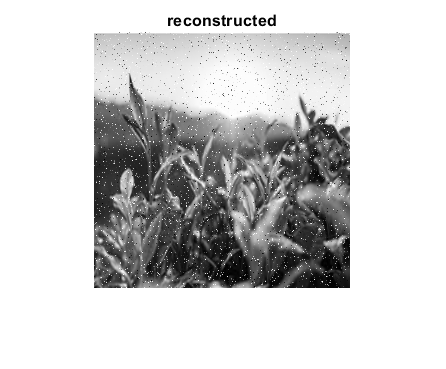


reconstructedCodificado = reshape(typecast(uint8(bin2dec(char(reshape(imgOutputCodificado, 8, [])+'0').')), orig_class), orig_size);
figure()
imshow(reconstructedCodificado); title('reconstructed')